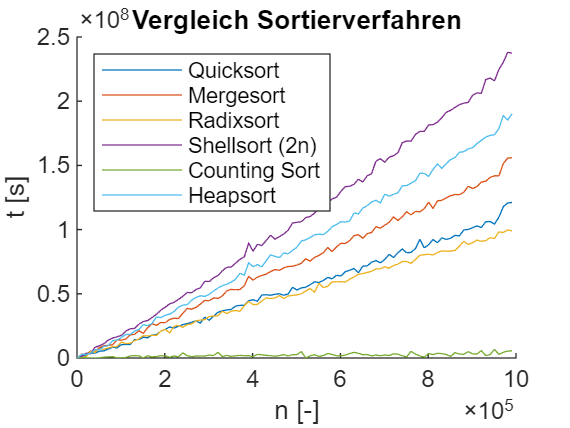

% File: plot_sortierverfahren.m
clear; clc;

basePath = 'C:\Users\Niklas\OneDrive\Desktop\Informatik 2.1';

files = {
    'quicksort.txt', 
    'mergesort.txt', 
    'radix.txt', 
    'shellsort_2n.txt', 
    'counting.txt', 
    'heapsort.txt'
};

labels = {
    'Quicksort', 
    'Mergesort', 
    'Radixsort', 
    'Shellsort (2n)', 
    'Counting Sort', 
    'Heapsort'
};

colors = lines(length(files));  % automatische Farbwahl
figure;
title('Vergleich Sortierverfahren');
xlabel('n [-]');
ylabel('t [s]');
hold on;

for i = 1:length(files)
    fullPath = fullfile(basePath, files{i});
    fid = fopen(fullPath, 'r');
    if fid == -1
        warning('Datei nicht gefunden: %s', fullPath);
        continue;
    end
    data = textscan(fid, '%d %f');
    fclose(fid);

    x = data{1};
    y = data{2};

    plot(x, y, 'DisplayName', labels{i}, 'Color', colors(i,:));
end

legend('Location', 'northwest');
hold off;